clc
clear all
close all

# Analisis Clásico

Graficar $\theta(t)$ y su derivada $\omega=\frac{d\theta}{dt}$ con condiciones iniciales $\theta_0=\{15\degree ,30\degree ,90\degree ,150\degree ,179\degree \}$ y $$\omega_0=1$$

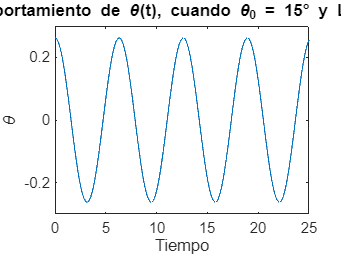

t=0:0.01:25;
grados=[15,30,90,150,179];
thetat=zeros(length(grados),length(t));
w=zeros(length(grados),length(t)-1);
wf=zeros(length(grados),length(t));
g=9.81;
L=g;
omega0=sqrt(g/L);
for i=1:length(grados)
    theta0=deg2rad(grados(i));
    K=ellipke(sin(theta0/2)^2);
    thetat(i,:)=2*asin(sin(theta0/2)*jacobiSN(K-omega0.*t,sin(theta0/2)^2));
    w(i,:)=diff(thetat(i,:));
    wf(i,:)=cat(2,w(i,:),w(i,end));
end

figure(1)
plot(t,thetat(1,:));
title('Comportamiento de \theta(t), cuando \theta_0 = 15° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\theta');

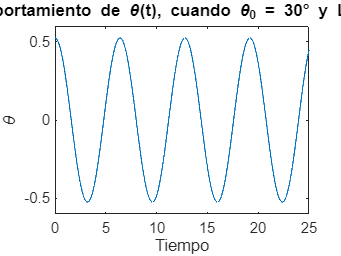


figure(2)
plot(t,thetat(2,:));
title('Comportamiento de \theta(t), cuando \theta_0 = 30° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\theta');

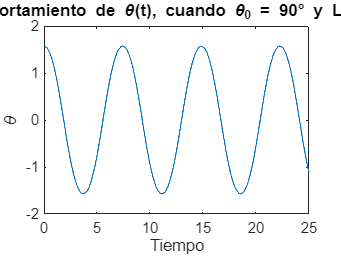


figure(3)
plot(t,thetat(3,:));
title('Comportamiento de \theta(t), cuando \theta_0 = 90° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\theta');

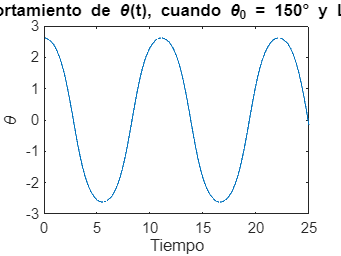


figure(4)
plot(t,thetat(4,:));
title('Comportamiento de \theta(t), cuando \theta_0 = 150° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\theta');

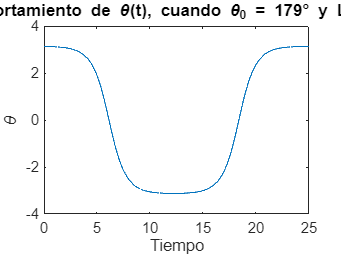


figure(5)
plot(t,thetat(5,:));
title('Comportamiento de \theta(t), cuando \theta_0 = 179° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\theta');

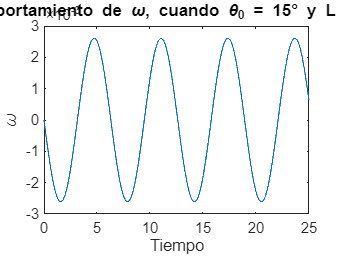


figure(6)
plot(t,wf(1,:));
title('Comportamiento de \omega, cuando \theta_0 = 15° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\omega');

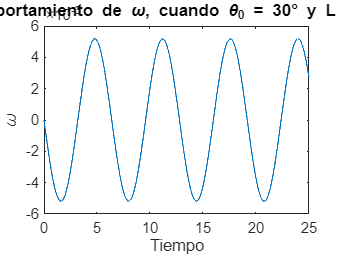


figure(7)
plot(t,wf(2,:));
title('Comportamiento de \omega, cuando \theta_0 = 30° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\omega');

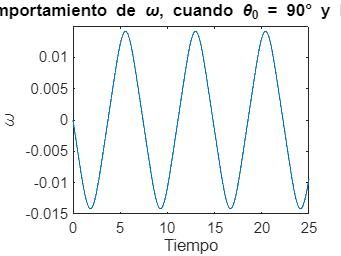


figure(8)
plot(t,wf(3,:));
title('Comportamiento de \omega, cuando \theta_0 = 90° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\omega');

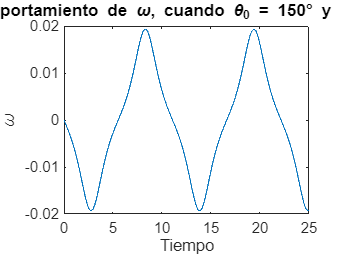


figure(9)
plot(t,wf(4,:));
title('Comportamiento de \omega, cuando \theta_0 = 150° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\omega');

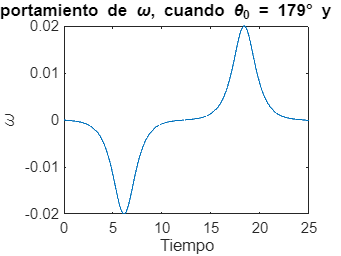


figure(10)
plot(t,wf(5,:));
title('Comportamiento de \omega, cuando \theta_0 = 179° y L = '+ string(L));
xlabel('Tiempo');
ylabel('\omega');

Graficar el diagrama de fase 

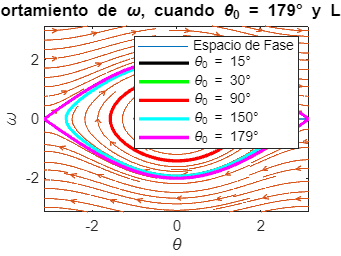

t2=t;
ddt=t(2)-t(1);
V=linspace(-pi,pi,length(t2));
[v,t2]=meshgrid(V,V);

dv=t2;
dt = -omega0^2.*sin(V); 
n = sqrt(dv.^2 + dt.^2); 
streamslice(v,t2,dv./n,dt./n);
hold on
xlim([-pi,pi]);
ylim([-pi,pi]);
legend('Espacio de Fase')

colores = {'k', 'g', 'r', 'c', 'm'}; 

plot(thetat(1,:), (1/ddt)*wf(1,:), 'LineWidth', 2,'DisplayName','\theta_0 = 15°', 'Color', colores{1})
plot(thetat(2,:), (1/ddt)*wf(2,:), 'LineWidth', 2,'DisplayName','\theta_0 = 30°', 'Color', colores{2})
plot(thetat(3,:), (1/ddt)*wf(3,:), 'LineWidth', 2,'DisplayName','\theta_0 = 90°', 'Color', colores{3})
plot(thetat(4,:), (1/ddt)*wf(4,:), 'LineWidth', 2,'DisplayName','\theta_0 = 150°', 'Color', colores{4})
plot(thetat(5,:), (1/ddt)*wf(5,:), 'LineWidth', 2,'DisplayName','\theta_0 = 179°', 'Color', colores{5})
hold off

xlabel('\theta');
ylabel('\omega');

legend

Densidad de probabilidad clásica

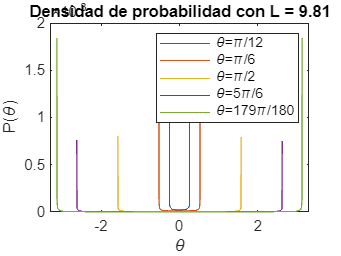

m=1;
g=9.81;
L=g;
grados=[15,30,90,150,179];
dtheta=0.001;
theta01=(grados(1));
theta02=(grados(2));
theta03=(grados(3));
theta04=(grados(4));
theta05=(grados(5));

E1=-m*g*L*cos(deg2rad(theta01));
E2=-m*g*L*cos(deg2rad(theta02));
E3=-m*g*L*cos(deg2rad(theta03));
E4=-m*g*L*cos(deg2rad(theta04));
E5=-m*g*L*cos(deg2rad(theta05));

theta1=deg2rad((-(abs(theta01)-dtheta):dtheta:abs(theta01)-dtheta));
theta2=deg2rad((-(abs(theta02)-dtheta):dtheta:abs(theta02)-dtheta));
theta3=deg2rad((-(abs(theta03)-dtheta):dtheta:abs(theta03)-dtheta));
theta4=deg2rad((-(abs(theta04)-dtheta):dtheta:abs(theta04)-dtheta));
theta5=deg2rad((-(abs(theta05)-dtheta):dtheta:abs(theta05)-dtheta));

U1=-m*g*L*cos(theta1);
U2=-m*g*L*cos(theta2);
U3=-m*g*L*cos(theta3);
U4=-m*g*L*cos(theta4);
U5=-m*g*L*cos(theta5);

P1=(1./(E1-U1)).^(1/2);
P1=P1./trapz(P1);

P2=(1./(E2-U2)).^(1/2);
P2=P2./trapz(P2);

P3=(1./(E3-U3)).^(1/2);
P3=P3./trapz(P3);

P4=(1./(E4-U4)).^(1/2);
P4=P4./trapz(P4);

P5=(1./(E5-U5)).^(1/2);
P5=P5./trapz(P5);

figure(12)
plot(theta1,P1,'DisplayName','\theta=\pi/12'); hold on
plot(theta2,P2,'DisplayName','\theta=\pi/6');
plot(theta3,P3,'DisplayName','\theta=\pi/2');
plot(theta4,P4,'DisplayName','\theta=5\pi/6');
plot(theta5,P5,'DisplayName','\theta=179\pi/180'); hold off
title('Densidad de probabilidad con L = '+ string(L));
xlabel('\theta');
ylabel('P(\theta)');
xlim([-3.3,3.3]);
legend

# Análisis Cuántico

clear all
close all
clc

L = 2;
m = 1;
g = 1;
h = 1;

theta0 = pi/4;
theta=-pi:0.0001:pi;


omega0 = pi/6;
eta = theta/2;
rf=30;

q = -(4*m^2*g*L^3) / h^2 ;

A = 1/sqrt(trapz(theta,(exp(-((theta-theta0)/omega0).^2)).^2));
a = 1/sqrt(pi);

phi0=A*exp(-((theta-theta0)/omega0).^2);


phit=zeros(31,length(theta));
ypar=zeros(31,length(theta));
yimpar=zeros(31,length(theta));

Cnp=zeros(1,31);
Enp=zeros(1,31);

Csp=zeros(1,31);
Esp=zeros(1,31);

j=1;

%Conseguir En y Cn
for i=0:2:rf*2

    [cep,cevp]=ce(i,q,theta/2);

    Cnp(j)=trapz(theta,a*conj(cep).*phi0);
    Enp(j)=(cevp*h^2)/(8*m*L^2);
    j=j+1;
end

j=1;

for i=2:2:rf*2
    [seim,sevim]=se(i,q,theta/2);

    Csp(j)=trapz(theta,a*conj(seim).*phi0);
    Esp(j)=(sevim*h^2)/(8*m*L^2);

    j=j+1;
end

phitpar=0;
phitimpar=0;
j=1;

for i=0:rf

    ypar(j,:)=a*ce(2*i,q,eta);

    phitpar=phitpar+Cnp(j)*ypar(j,:);

    yimpar(j,:)=a*se(2*i+2,q,eta);

    phitimpar=phitimpar+Csp(j)*yimpar(j,:);

    phit(j,:)=phitimpar+phitpar;

    j=j+1;
end


Primeros 30 eigenenergias

eigpar=Enp;
eigimpar=Esp;

Primeros 30 Coeficientes

Cnpar=Cnp;
Cnimpar=Csp;

Graficar los primeros 6 eigenestados

figure(14)
ax1=subplot(3,3,1,polaraxes);
polarplot(ax1,theta,abs(ypar(1,:)).^2 + L);
ax1.ThetaZeroLocation = 'bottom';
title('ce0')

ax2=subplot(3,3,2,polaraxes);
polarplot(ax2,theta,abs(ypar(2,:)).^2 + L);
ax2.ThetaZeroLocation = 'bottom';
title('ce2')

ax3=subplot(3,3,3,polaraxes);
polarplot(ax3,theta,abs(ypar(3,:)).^2 + L);
ax3.ThetaZeroLocation = 'bottom';
title('ce4')

ax4=subplot(3,3,4,polaraxes);
polarplot(ax4,theta,abs(yimpar(1,:)).^2 + L); 
ax4.ThetaZeroLocation = 'bottom';
title('se2')

ax5=subplot(3,3,5,polaraxes);
polarplot(ax5,theta,abs(yimpar(2,:)).^2 + L);
ax5.ThetaZeroLocation = 'bottom';
title('se4')

ax6=subplot(3,3,6,polaraxes);
polarplot(ax6,theta,abs(yimpar(3,:)).^2 + L);
ax6.ThetaZeroLocation = 'bottom';
title('se6')

Valor esperado de la posición en el tiempo

clear i; clear j
tcua=0:0.1:150;
esptheta=zeros(1,length(tcua));

myVideo = VideoWriter('myVideoFile4'); %open video file
myVideo.FrameRate = 30;  %can adjust this, 5 - 10 works well for me
open(myVideo)

for j=1:length(tcua)
    phi=zeros(1,length(theta));
    for k=1:length(Enp)
        tpar=exp(-i*Enp(k)*tcua(j)/h);
        timpar=exp(-i*Esp(k)*tcua(j)/h);

        phipar=a*ce(2*k-2,q,eta);
        phiimpar=a*se(2*k,q,eta);

        phi=phi+Cnp(k)*phipar*tpar+Csp(k)*phiimpar*timpar;

        polarplot(theta,abs(phi).^2 + L); 

        pause(0.001) 
        frame = getframe(gcf); 
        writeVideo(myVideo, frame);
    end
    etheta=trapz(theta,abs(phi).^2.*theta);
    esptheta(j)=etheta;
end
close(myVideo);
plot(tcua,esptheta);
title('Valor esperado de \theta')
xlabel('t');
ylabel('\theta');

Analogia Punto 6

clear phitpar, clear phitimpar
j=20;
ypar=0;
yimpar=0;
phitpar=0;
phitimpar=0;
phitt=0;


for i=j:rf

    ypar=a*ce(2*i-2,q,eta);

    phitpar=phitpar+Cnp(i)*ypar;

    yimpar=a*se(2*i,q,eta);

    phitimpar=phitimpar+Csp(i)*yimpar;


    phitt=phitimpar+phitpar+phitt;
end

proba=phitt*sqrt(1/trapz(theta,abs(phitt).^2));
plot(theta,abs(proba).^2);